rng('default')
fs = 100;                                % sample frequency (Hz)
t = 0:1/fs:10-1/fs;                      % 10 second span time vector
x = (1.3)*sin(2*pi*15*t) ...             % 15 Hz component
  + (1.7)*sin(2*pi*40*(t-2)) ...         % 40 Hz component
  + 2.5*randn(size(t));                  % Gaussian noise;

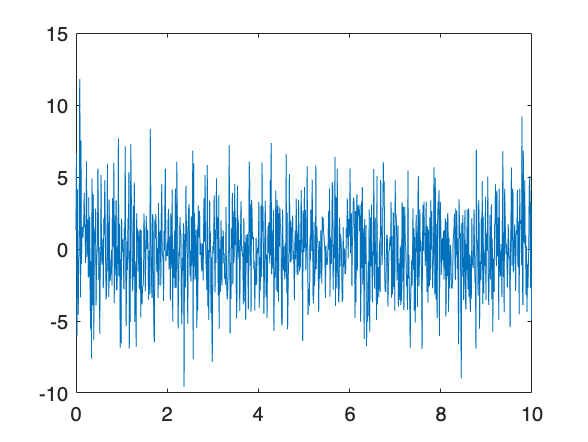

plot(t,x);

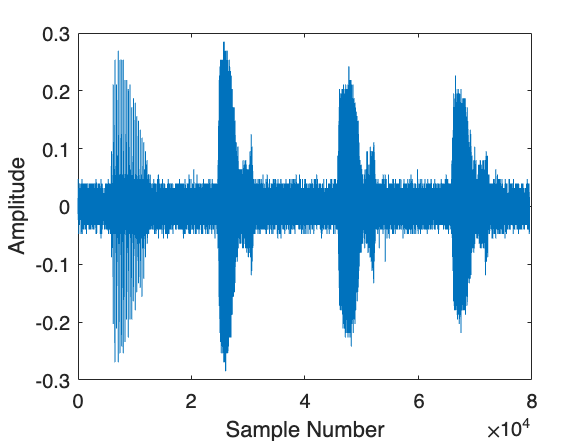

whaleFile = 'bluewhale.au';
[x,fs] = audioread(whaleFile);

plot(x)
xlabel('Sample Number')
ylabel('Amplitude')

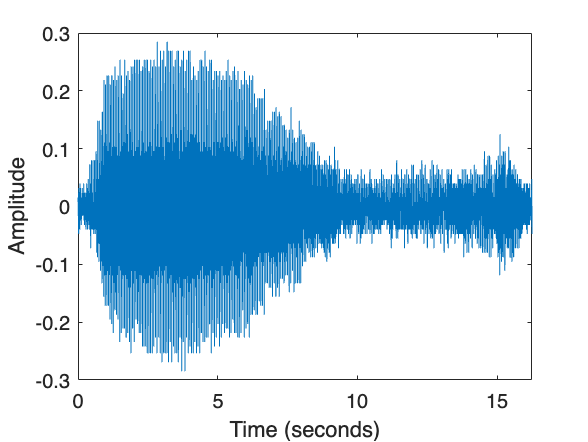

moan = x(2.45e4:3.10e4);
t = 10*(0:1/fs:(length(moan)-1)/fs);

plot(t,moan)
xlabel('Time (seconds)')
ylabel('Amplitude')
xlim([0 t(end)])

m = length(moan);
n = pow2(nextpow2(m));
y = fft(moan,n);

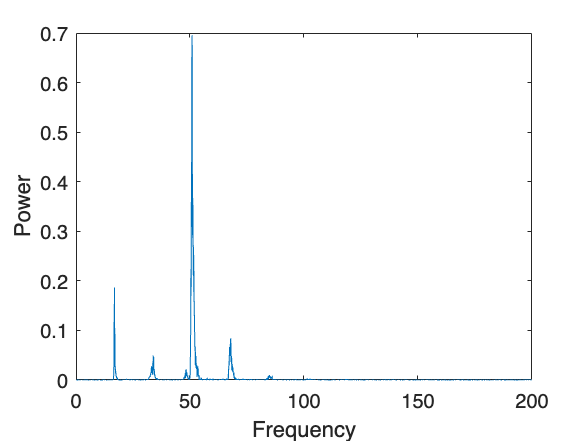

f = (0:n-1)*(fs/n)/10;
power = abs(y).^2/n;

plot(f(1:floor(n/2)),power(1:floor(n/2)))
xlabel('Frequency')
ylabel('Power')